# Лабораторна робота №1

Яковець А., варіант 15

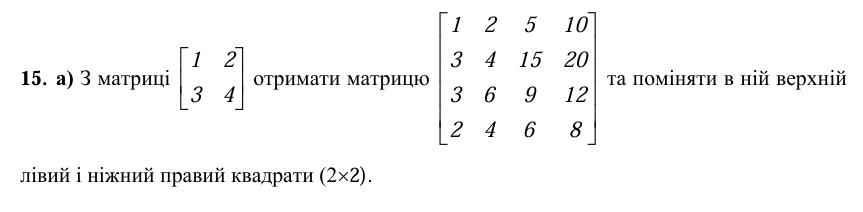

Отримуєм матрицю

a = [1 2; 
    3 4];

r1 = a(1,:)

r1 =      1     2


r2 = a(2,:)

r2 =      3     4



c1 = a(:,1)

c1 =      1
     3


c11 = c1.'

c11 =      1     3


c2 = a(:,2)

c2 =      2
     4


c22 = c2.'

c22 =      2     4



A11 = a;
A12 = 5*a;
A21 = [3.*r1;
    c22]

A21 =      3     6
     2     4


A22 = [3.*r2;
    2.*r2]

A22 =      9    12
     6     8



A = [A11 A12;
    A21 A22]

A =      1     2     5    10
     3     4    15    20
     3     6     9    12
     2     4     6     8


Міняєм верхній лівий і нижній правий квадрати

A = [A22 A12;
    A21 A11]

A =      9    12     5    10
     6     8    15    20
     3     6     1     2
     2     4     3     4


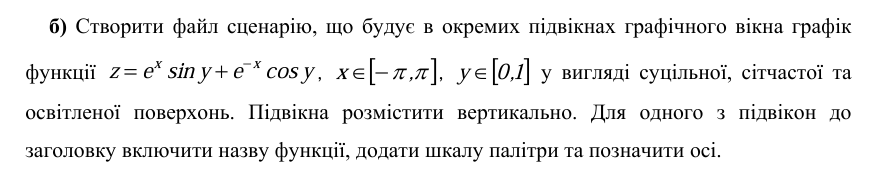

x = -pi:0.01:pi;
y = 0:0.01:1;
[X, Y] = meshgrid(x, y);
Z = exp(X).*sin(Y) + exp(-X).*cos(Y);

Суцільна поверхня

subplot(3,1,1);
surf(X, Y, Z);
shading interp;
grid on;
title('z = e^x*sin(y) + e^{-x}*cos(y)');
xlabel('x');
ylabel('y');
zlabel('z');
colorbar;

Сітчаста поверхня

subplot(3,1,2);
mesh(X(1:10:end,1:10:end), Y(1:10:end,1:10:end), Z(1:10:end,1:10:end))
shading faceted;
grid on;

Освітлена поверхня

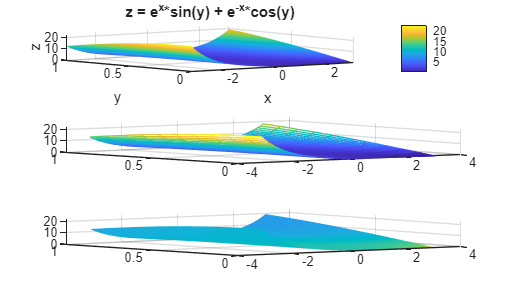

subplot(3,1,3);
surfl(X, Y, Z);
shading interp;
grid on;